% 1.
% Define symbolic impulse response h(t)
syms hz(t)
Dh = diff(hz, t);
D2h = diff(hz, t, 2);

% Differential equation: 2*d²h/dt² + dh/dt + 4*h = 0
ode = 2*D2h + Dh + 4*hz == 0;

% Initial conditions: h(0) = 0, h'(0) = 1
conds = [hz(0) == 0, Dh(0) == 1];

% Solve the differential equation
hSol(t) = dsolve(ode, conds);
hSol(t) = simplify(hSol);

% Make the solution causal: h(t) = hSol(t) * u(t)
% (i.e., h(t) = 0 for t < 0)
hCausal(t) = piecewise(t < 0, 0, hSol(t));

% Display the result
disp('Causal Impulse Response h(t):');

Causal Impulse Response h(t):


disp(hCausal);

$$\left\{ \begin{array}{cl} 0 & \text{ if }t<0\\ \frac{4\,\sqrt{31}\,{\mathrm{e}}^{-\frac{t}{4}}\,\sin\left(\frac{\sqrt{31}\,t}{4}\right)}{31} & \mathrm{otherwise} \end{array}\right.$$

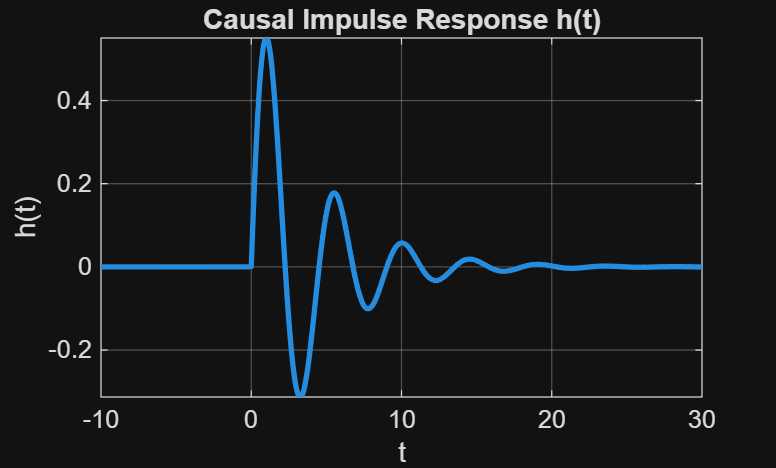


% Plot h(t) over desired range
fplot(hCausal, [-10, 30], 'LineWidth', 2);
title('Causal Impulse Response h(t)');
xlabel('t');
ylabel('h(t)');
grid on;

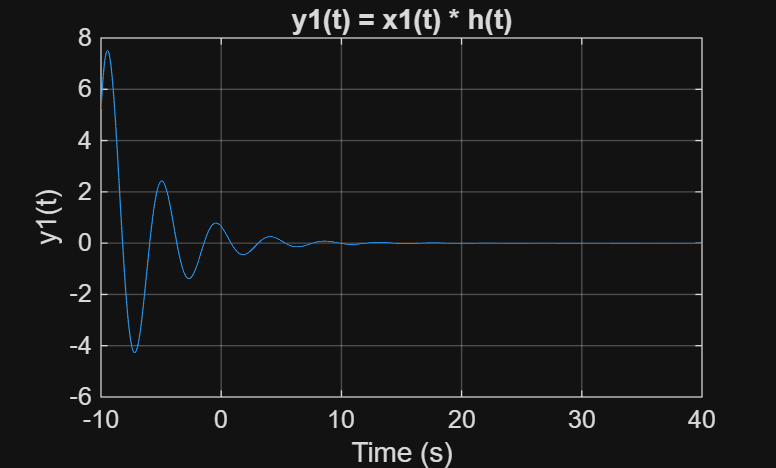

% 2.
% Define time vector
t = -10:0.01:40;

% Convert symbolic h(t) to a numeric function handle
h_func = matlabFunction(hSol);

% Evaluate h(t) numerically
h_vals = h_func(t);

% Define x1(t): 5 for 0 <= t < 10
x1_vals = 5 * (t >= 0 & t < 10);

% Define x2(t): time-shifted version of x1(t)
x2_vals = 2 * (t >= 10 & t < 20);  % since x2(t) = 2 * x1(t - 10)

% Linear combination of inputs
x_comb_vals = x1_vals + x2_vals;

% Convolution step size
dt = 0.01;

% Compute convolutions
y1 = conv(x1_vals, h_vals, 'same') * dt;
y2 = conv(x2_vals, h_vals, 'same') * dt;
y_comb = conv(x_comb_vals, h_vals, 'same') * dt;

% Plot y1(t)
figure;
plot(t, y1);
title('y1(t) = x1(t) * h(t)');
xlabel('Time (s)');
ylabel('y1(t)');
grid on;

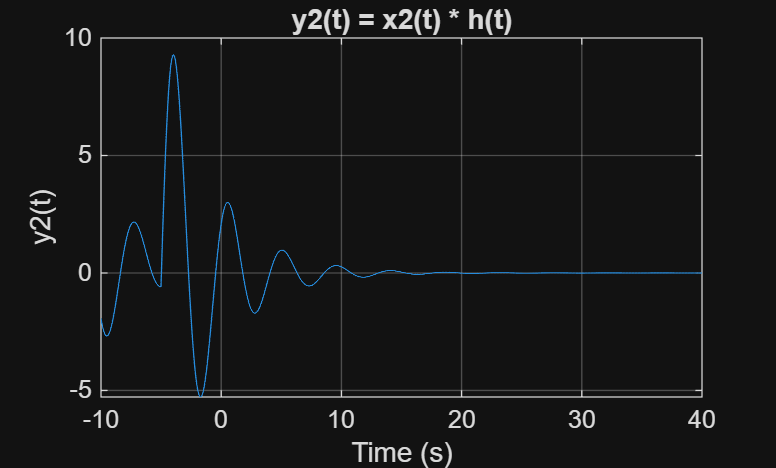


% Plot y2(t)
figure;
plot(t, y2);
title('y2(t) = x2(t) * h(t)');
xlabel('Time (s)');
ylabel('y2(t)');
grid on;

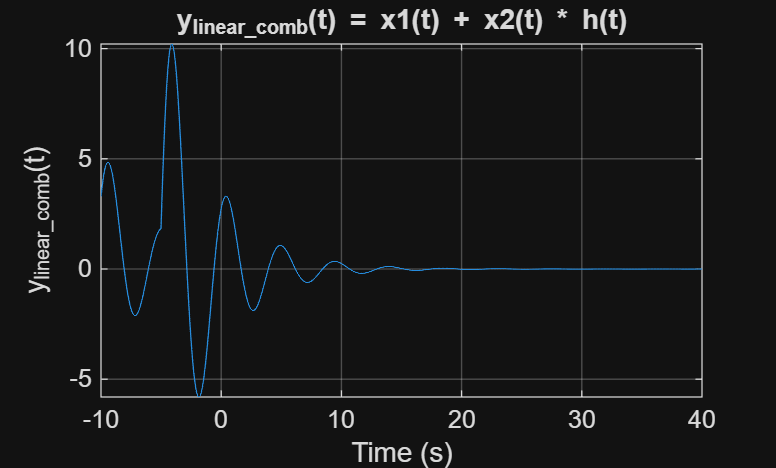


% Plot y_comb(t)
figure;
plot(t, y_comb);
title('y_{linear\_comb}(t) = x1(t) + x2(t) * h(t)');
xlabel('Time (s)');
ylabel('y_{linear\_comb}(t)');
grid on;

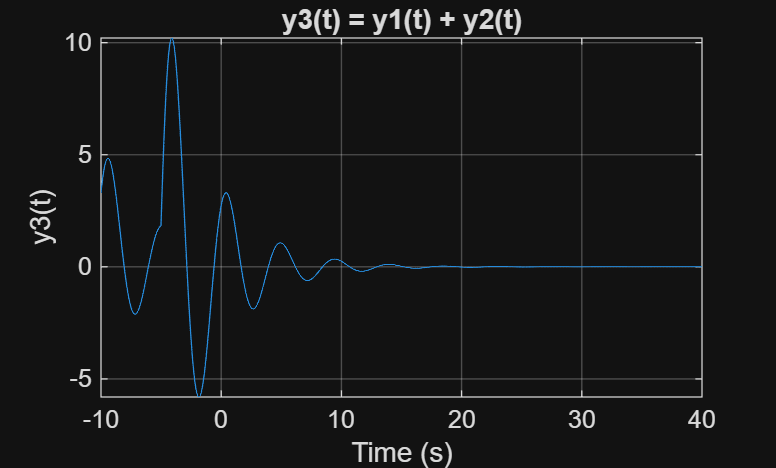


% Plot y3 = y1 + y2
y3 = y1 + y2;

figure;
plot(t, y3);
title('y3(t) = y1(t) + y2(t)');
xlabel('Time (s)');
ylabel('y3(t)');
grid on;


% Comparison
disp('y3(t) and y_linear_comb(t) should match due to linearity.');

y3(t) and y_linear_comb(t) should match due to linearity.


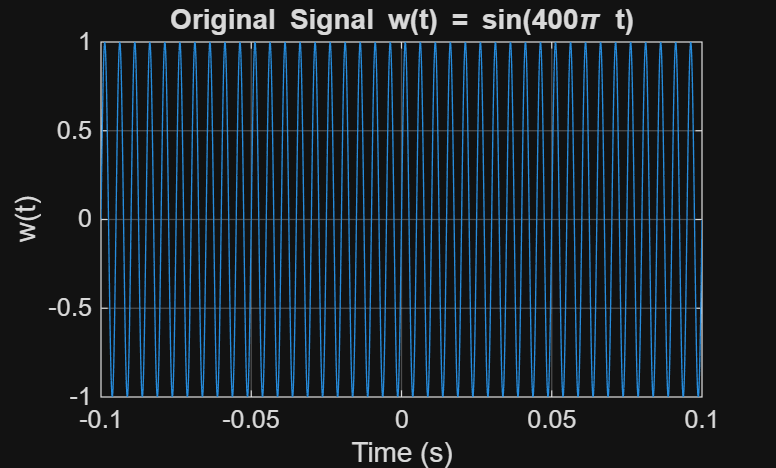

% 3.
% Define time vector
t = -0.1:0.0001:0.1; % Time range with high resolution

% Define the original signal w(t)
w = sin(400 * pi * t);

% Define the input signal x(t)
x = cos(100 * pi * t) + sin(400 * pi * t) - cos(800 * pi * t);
x(t < 0) = 0; % Apply unit step function u(t)

% Define the filter impulse response h(t)
h = 400 * exp(-200 * t) .* cos(400 * pi * t);
h(t < 0) = 0; % Apply unit step function u(t)

% Perform convolution
y = conv(x, h, 'same') * 0.0001; % Convolution and scale by dT

% Plot the original signal w(t)
figure;
plot(t, w);
title('Original Signal w(t) = sin(400\pi t)');
xlabel('Time (s)');
ylabel('w(t)');
grid on;

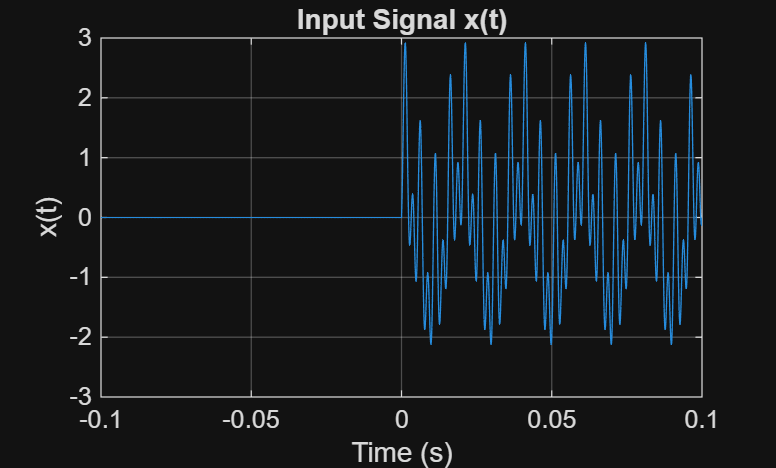


% Plot the input signal x(t)
figure;
plot(t, x);
title('Input Signal x(t)');
xlabel('Time (s)');
ylabel('x(t)');
grid on;

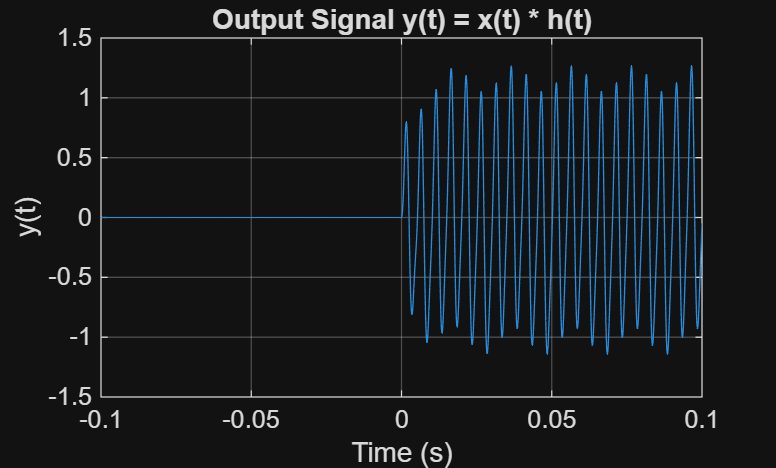


% Plot the output signal y(t)
figure;
plot(t, y);
title('Output Signal y(t) = x(t) * h(t)');
xlabel('Time (s)');
ylabel('y(t)');
grid on;


% Comment on the effect of the filter
disp('The filter reduces the amplitude of the high-frequency components in the input signal x(t).');

The filter reduces the amplitude of the high-frequency components in the input signal x(t).
